clc
close all
clear

L = 1e-9;                 % 1 nm
e = 1.6e-19;              % C
kT = 0.0259 * e;          % J
h_bar = (6.626e-34) / (2 * pi);
m_o = 9.1e-31;            % kg
m_t = 0.19 * m_o;         % in-plane effective mass
m_z = 0.98 * m_o;         % confinement direction

% 2D DOS per subband
g_2D = m_t / (pi * h_bar^2);

% Calculating for 5 subbband energies
En = zeros(1, 5);
for n = 1:5
    En(n) = (h_bar^2 * (n * pi / L)^2) / (2 * m_z);
end
E1 = En(1);

Since there are discrete subbands we must acount for them when calculating the Fermi-level energy. I originally tried using fsolve() for this, but I struggled and had problems obtaining a graph that looked like this.

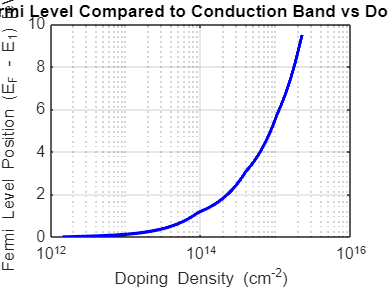

% Sweep a range of Ef values (J)
Ef_range = linspace(E1, En(end) + 10*kT, 1000);
n_vals = zeros(size(Ef_range));

% Loop over Ef and compute total density
for i = 1:length(Ef_range)
    Ef = Ef_range(i);
    n_total = 0;
    for n = 1:5
        n_total = n_total + g_2D * kT * log(1 + exp((Ef - En(n)) / kT));
    end
    n_vals(i) = n_total;
end

n = n_vals / 1e4;

% Convert Ef to eV relative to the bulk conduction band
Ef_rel = (Ef_range - E1) / e;

% Plot
figure;
semilogx(n, Ef_rel, 'b', 'LineWidth', 2);
xlabel('Doping Density (cm^{-2})');
ylabel('Fermi Level Position (E_F - E_1) [eV]');
title('Fermi Level Compared to Conduction Band vs Doping');
grid on;

Now you can see that this follows the exponential what we might expect. It will gradually take us greater and greater doping to increase the fermi-level. The subbands of the well introduce steps within the plot that make it different than a typical 3D, unbounded, plot.

I'm having difficulty plotting any values for doping as high as 10^16 and above with the logarithms. This property of the graph still stays the same, with the steps being introduced from the subbands.